# ARMA Forecasting

We have spent a lot of time trying to model the time series structure of the data. Now it is time to use the model! 

And what is a good ARMA model for? Well, you can generate forecasts with it. You can try to use the past to make educated guesses of the future. We will find however, that it is often a very depressing affair. Oftentimes, a random walk model, although it does not capture the time series structure, outperforms a more sophisticated ARMA model in generating forecast. There could be several reasons for this outcome. For example, the parameters could change from time to time, and the non-stationarity that this parameter instability generates may lead to the present observations being a robust forecast that outperforms parametric models. 

Remember that building a good time series model is often a different beast than building a good forecasting model. We target a different outcome. When we build a good time series model, we aim to minimise the serial dependence of the error term. When we build a good forecasting model, we aim to minimise the prediction error. If the data generating process is stable, then the two targets overlap. But in a world of non-stationarity, the two targets may be different.

## **Exercise** 60

Let's begin by loading our term premium data:

clear all
clc
load term_premium

The exercise tells us to use 50% of the sample to estimate the model and 50% to evaluate the forecasts. Therefore, we need to find the id of this midpoint in our sample.

T50 = floor(length(tp)/2)

T50 =    400


From the previous section, remember that our preferred model is an ARMA(1,1). Let's first estimate our model one more time to remember the parameter values.

% Setting the optimization display options:
options.Display='none';
% Estimating the model:
p = armaxfilter(tp(1:T50),1,1,1,[],[], options)

p =       0.05455
      0.89559
        0.459


Exercise 60 asks us to produce 1-step forecasts and compare these forecasts with those of a random-walk model. Exercise 61, on the other hand, asks us to perform the same analysis using 3-step forecasts. These two exercises can be simplified into one by setting a variable for the number of forecast steps. We call this variable `h`:

% Setting the h period ahead forecasts:
h = 1; 

As usual, the MFE Toolbox has a function that makes our lives a lot easier. In this case, the function is called `arma_forecaster`. Let's take a look:

help arma_forecaster

  Produces h-step ahead forecasts from ARMA(P,Q) models starting at some point in the sample, R, and
  ending at the end of the sample.  Also shifts the data to align y(t+h) with y(t+h|t) in slot t,
  computes the theoretical forecast standard deviation (assuming homoskedasticity) and the forecast
  errors.
 
  USAGE:
   [YHATTPH] = arma_forecaster(Y,PARAMETERS,CONSTANT,P,Q,R,H)
   [YHATTPH,YTPH,FORERR,YSTD] = arma_forecaster(Y,PARAMETERS,CONSTANT,P,Q,R,H,SEREGRESSION)
 
  INPUTS:
    Y            - A column of data
    CONSTANT     - Scalar variable: 1 if the model includes a constant, 0 to exclude
    P            - Non-negative integer vector representing the AR orders included in the model.
    Q            - Non-negative integer vector representing the MA orders included in the model.
    R            - Length of sample used in estimation.  Sample is split up between R and P, where
                     the first R (regression) are used for estimat

Now let's use this function to perform the forecasts. We will store the forecasted values, the true values, and the forecast errors:

[fc_arma, y, fe_arma] = arma_forecaster(tp,p,1,1,1,T50,h);

When we take a look at the structure of the forecast, we notice that the first observations, in fact the first half sample, are NANs. The second half sample consists of the h-step ahead forecasts.

fc_arma(1:5)

ans =    NaN
   NaN
   NaN
   NaN
   NaN


fc_arma(T50-3:T50+3)

ans =           NaN
          NaN
          NaN
       0.9847
       1.2823
       1.7417
       1.5715


fc_arma(end-5:end)

ans =        0.1346
     -0.19687
    0.0094561
      0.18567
      0.29443
      0.33933


Since we are asked to compare these forecasts with those of a random-walk model, we will also need to create the forecasts for a random-walk model. Remember that in the random-walk model, we only have an AR coefficient and this coefficient is equal to one. Therefore:

% Generating the random-walk forecasts:
[fc_rw, ~, fe_rw] = arma_forecaster(tp,1,0,1,0,T50,h);

% Just organizing the data for analysis:
errors = [fe_arma fe_rw];
% Checking where both are not NaN:
valid = all(~isnan(errors),2);
errors = errors(valid,:);
fc_dates = dates(valid);
% Standardizing the residuals:
std_forecast_errors = errors./std(errors);

Ok! Now let's do some plots! The first will be the different forecast errors. 

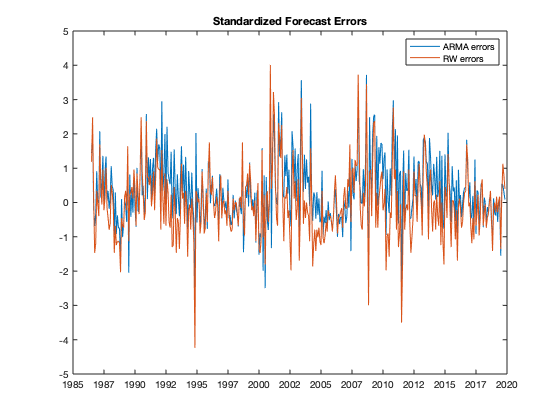

figure()
plot(fc_dates, std_forecast_errors)
datetick('x')
legend('ARMA errors', 'RW errors')
title('Standardized Forecast Errors')

From eyeballing the graph, we see that the ARMA errors tend to be bigger. This is one example when the ARMA model is worse than the RW model to make forecasts. The most likely reason is that the parameters of the time-series model are not constant. 

We can also compare the forecasts to the actual realisations in the last `s` periods. 

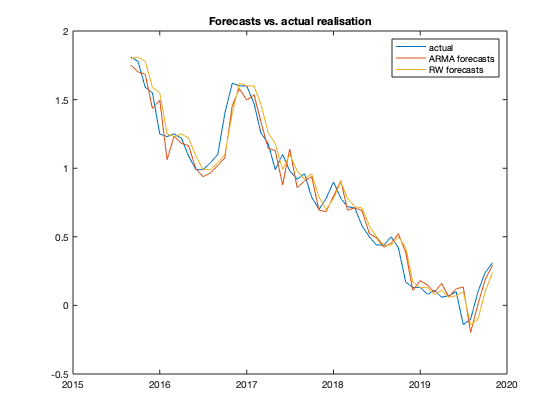

% First setting the size of the period we want to compare:
s=50;

% Now doing the plot:
figure()
forecasts = [y fc_arma fc_rw];
forecasts = forecasts(valid,:);
plot(fc_dates(end-s:end), forecasts(end-s:end,:)) 
legend('actual', 'ARMA forecasts', 'RW forecasts')
title('Forecasts vs. actual realisation')
datetick('x')

We can finally compare the forecasts using the Mean Squared Error (MSE) or the Mean Absolute Error (MAE). These metrics are just the average of the squared and absolute error terms. Therefore, it is very straightforward to calculate them. 

mse_fe = mean(errors.^2)

mse_fe =      0.035198     0.031247


mae_fe = mean(abs(errors))

mae_fe =       0.13901      0.13077


The results from the MSE and MAE show that, indeed, the random-walk model performs marginally better than our selected ARMA(1,1) in forecasting. The lesson here is: forecasting the first moment (i.e. mean) of time series is very hard :(

But life is not just bad news folks! As we saw in Kevin's lecture and we will see in our MATLAB class next week, we are a lot more successful when we model second moments dynamics!